# Plant Model

%This code is a stability analysis for the smooth portion of the hybrid fly
%model.  It serves to investigate the gain space as well as the effects of
%neurological delay.

%Make sure to open the HybridSystemPerformance project.  This will set up
%paths correctly and clear the workspace.
clearvars -except commonPath
plantPath = strcat(commonPath,'\Plant Model\');
latestPlant = latestTimeParse(plantPath,'plant');
load(latestPlant);

Kp = 2.0000e-10

Ki = 1.0000e-12

td = 0.0400

# Binary Stability Field data

maxsize = 1317141

     Piecewise cubic interpolant:
       sf(x,y) = piecewise cubic surface computed from p
     Coefficients:
       p = coefficient structure



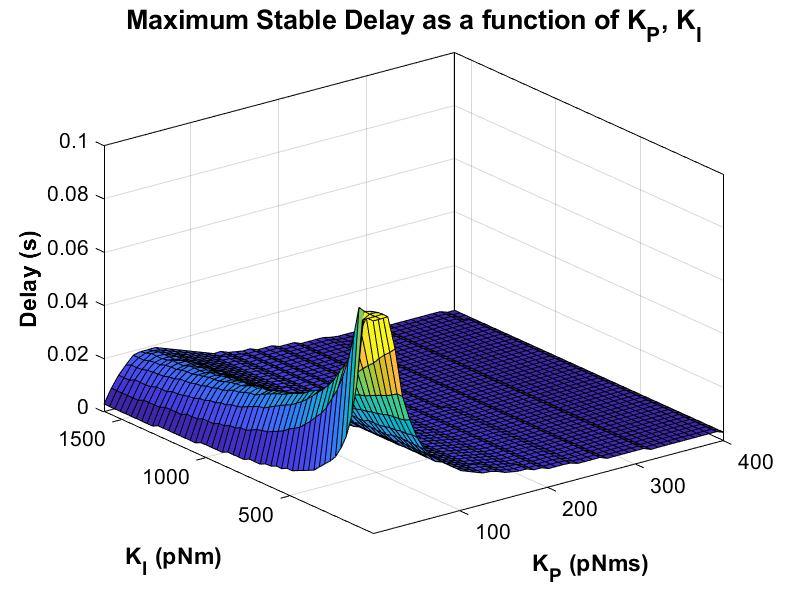

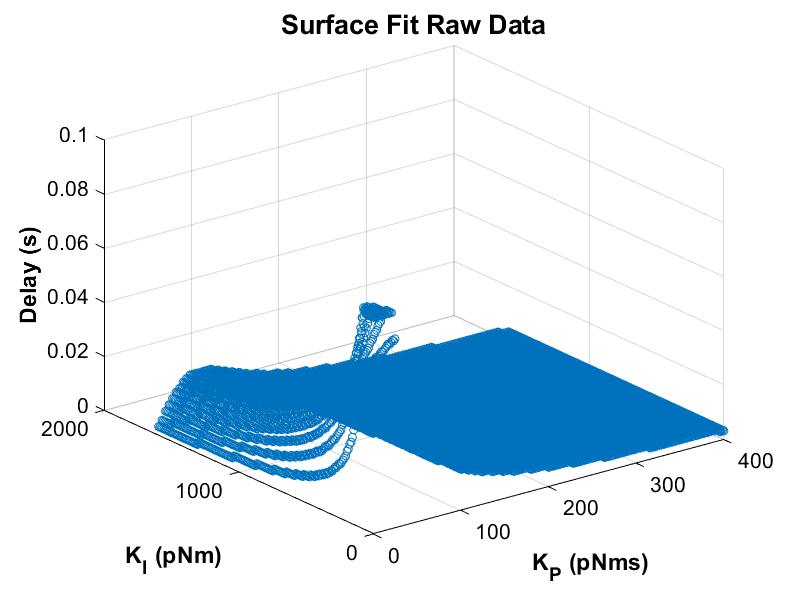

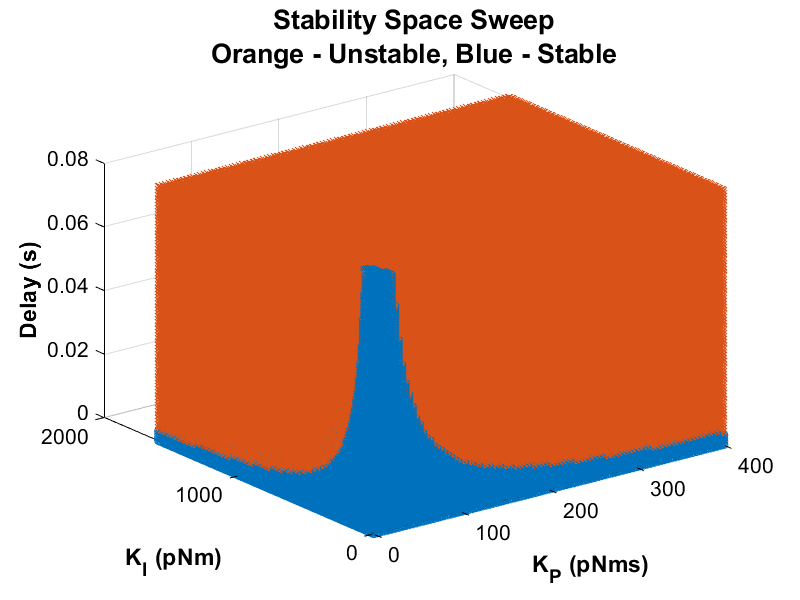

%Gain ranges
Kp = 1:4:401;
Ki = 1:10:1601;
td = 0:0.001:0.08; %s
%Size of data space
maxsize = size(Kp,2)*size(Ki,2)*size(td,2)

%Storage arrays preallocated at maximum size - trimmed post loop
stable = zeros(maxsize,3);
st = 1;
unstable = zeros(maxsize,3);
ust = 1;
stabletip = zeros(size(Kp,2)*size(Ki,2),3);
stc = 1;

%Run stability cases
for i = 1:size(Kp,2)
    tic
    for j = 1:size(Ki,2)
        for k = 1:size(td,2)
            
            %Delay (Pade approximation)
            [nump,denp]=padeWrap(td(k));
            d_tf = tf(nump,denp);
            
            %Closed Loop Transfer Function
            C_tf = tf([Kp(i) Ki(j)],[1 0]);
            num = d_tf*C_tf*G_plant;
            den = (1 + num);
            cl_tf = num/den;

            
            %Stability check and array placement
            s = isstablemod(cl_tf);
            if s == 1
                stable(st,:) = [Kp(i) Ki(j) td(k)];
                stt = st;
                st = st + 1;
            else
                unstable(ust,:) = [Kp(i) Ki(j) td(k)];
                ust = ust + 1;    
            end
        end
        stabletip(stc,:) = stable(stt,:);
        stc = stc + 1;
    end
    toc
end

%Trim stability arrays
if st == 1
    stable = [];
else
    stable = stable(1:st-1,:);
end

if ust == 1
    unstable = [];
else
    unstable = unstable(1:ust-1,:);
end

%Save Data file
basepath = strcat(commonPath,'\Stability Sweep Data');
savePath = genFileName(basepath,'stabilitySweep');
save(savePath,'stable','stabletip','unstable','Kp','Ki','td')
